# Introduction

The new version operates much like the R package rerddap.  There are two steps in getting data - the first is to get information about the dataset,  the second is to use that information in order to make an extract.  There are 5 main functons.  The first is used to find the information about the dataset:

function [ info ] = erddapInfo( datasetID, varargin )

Here the datasetD is a string containing a valid ERDDAP datasetID,  say 'erdSWchla8day', and "varargin" is an optional second argument,  which if given is the base URL of the ERDDAP server.  The default URL if not given is 'https://upwell.pfeg.noaa.gov/erddap".

There are three extraction routines:

function [extractStruct] = xtracto(info, parameter, xpos, ypos, varargin)

function [extract] = xtracto_3D(info, parameter, xpos, ypos, varargin )

function [extract, xlon, xlat, xtime] = xtractogon(info, parameter, xpoly, ypoly, varargin);

In each of these  "info" is the result of a call to erddapInfo() and "parameter" is a string containing the name of the parameter to extract from that dataset, say 'sst'.  In "xtracto()",  xpos and ypos are vectors of the x- (longitude) and y- (latitude) positions.  The option arguments in varargin can include a cell-array of time,  and a value "xlen" and "ylen" that define a box around (xpos, ypos) in which to make the extract.  The form of the default value of "xlen" and "ylen" is 0.,  and the default value of "tpos" is NaN.  To pass a cell array of times "tpos",  you must  tell the function that is what is being passed in the form:

extract = xtracto(info, parameter, xpos, ypos, 'tpos', tpos);

Similarly for "xlen" and "ylen":

extract = xtracto(info, parameter, xpos, ypos, 'tpos', tpos, 'xlen', xlen, 'ylen', ylen);

In "xtracto_3D()", "xpos" and "ypos" are vectors of length 2 giving the longitude and latitude bounds for the extract.  The optional argument "varargin" is the means to pass a cell array of bounding times, "tpos",  also of length 2.

In "xtractogon()", "xpoly" and "ypoly" are arrays defining the polygon in which to perform the extract.  Otherwise the arguments are the same as in "xtracto_3D()".

There is one mapping routine:

function [] = makeMap(extract, time_period, varargin)

which requires the Matlab package "m_map"  (https://www.eoas.ubc.ca/~rich/map.html), and will plot the results from either ""xtracto_3D()" or "xtractogon()".   "extract" here is the result from calling either "xtracto_3D()" or "xtractogon()", time period is one of the time periods in the extract  (and must be as given in "extract",  see example), and the optional argument "varargin" is a function to be applied to the data before plotting.  For example:

myfun = @(x)log(x);

makeMap(extract, extract.time(1, :), myfun);

# track data example

## Marlin tag data and chla

% load the included Marlin tag data
load('Marlin38606.mat');
xpos = Marlin38606.lon';
ypos = Marlin38606.lat';
tpos = Marlin38606.date;
tpos = datenum(tpos);
tpos = cellstr(datestr(tpos,'yyyy-mm-dd' ));
%  get Seawifs chlorophyll
swchlInfo = erddapInfo('erdSWchla8day');
swchlExtract = xtracto(swchlInfo, 'chlorophyll', xpos, ypos, 'tpos', tpos, 'xlen', .2, 'ylen', .2);


## Marlin tag data and bathymetry


% Marlin Tag data and bathymetry
etopo_info = erddapInfo('etopo360');

etopo_info = struct with fields:
        access: [1×1 struct]
    dimensions: [1×1 struct]


topo = xtracto(etopo_info, 'altitude', xpos, ypos, 'xlen', .2, 'ylen', .2 );


# gridded data examples

## Bathymetry Example

xpos = [235 240];
ypos = [36 39];
bathy_info = erddapInfo('etopo360');
bathy = xtracto_3D(bathy_info, 'altitude', xpos, ypos);
makeMap(SeaWiFS, SeaWiFS.time(1, :), myfun)


## SeaWiFs Chlorophyll

xpos = [235 240];
ypos = [36 39];

tpos{1} = '1998-01-16';
tpos{2} = 'last';

seawifs_info = erddapInfo('erdSWchlamday');
SeaWiFS = xtracto_3D(seawifs_info, 'chlorophyll', xpos, ypos, tpos);
myfun = @(x)log(x);
makeMap(SeaWiFS, SeaWiFS.time(1, :), myfun);

## MODIS chla for same bounds

%MODIS chla for same bounds
xpos = [235 240];
ypos = [36 39];
tpos{1} = '2003-01-16';
tpos{2} = 'last';
modis_info = erddapInfo('erdMH1chlamday');
MODIS = xtracto_3D(modis_info, 'chlorophyll', xpos, ypos, tpos);
myfun = @(x)log(x);
makeMap(MODIS, MODIS.time(1, :), myfun);


% VIIS chla for same bounds
tpos{1} = '2012-01-15';
viirs_info = erddapInfo('erdVH3chlamday');
VIIRS = xtracto_3D(viirs_info, 'chla', xpos, ypos, tpos);
myfun = @(x)log(x);
makeMap(VIIRS, VIIRS.time(1, :), myfun);


%upwelling
xpos= [238 238];
ypos = [37 37];
tpos{1} = '2005-01-01';
tpos{2} = '2005-12-31';
transport_info = erddapInfo('erdlasFnTran6');
ektrx = xtracto_3D(transport_info , 'ektrx', xpos, ypos, tpos);
ektry = xtracto_3D(transport_info, 'ektry', xpos, ypos, tpos);
upwelling  = upwell(ektrx.ektrx78, ektry.ektry, 152);

times = datenum(ektrx.time);
plot(times, upwelling);
datetick('x', 'mmm')



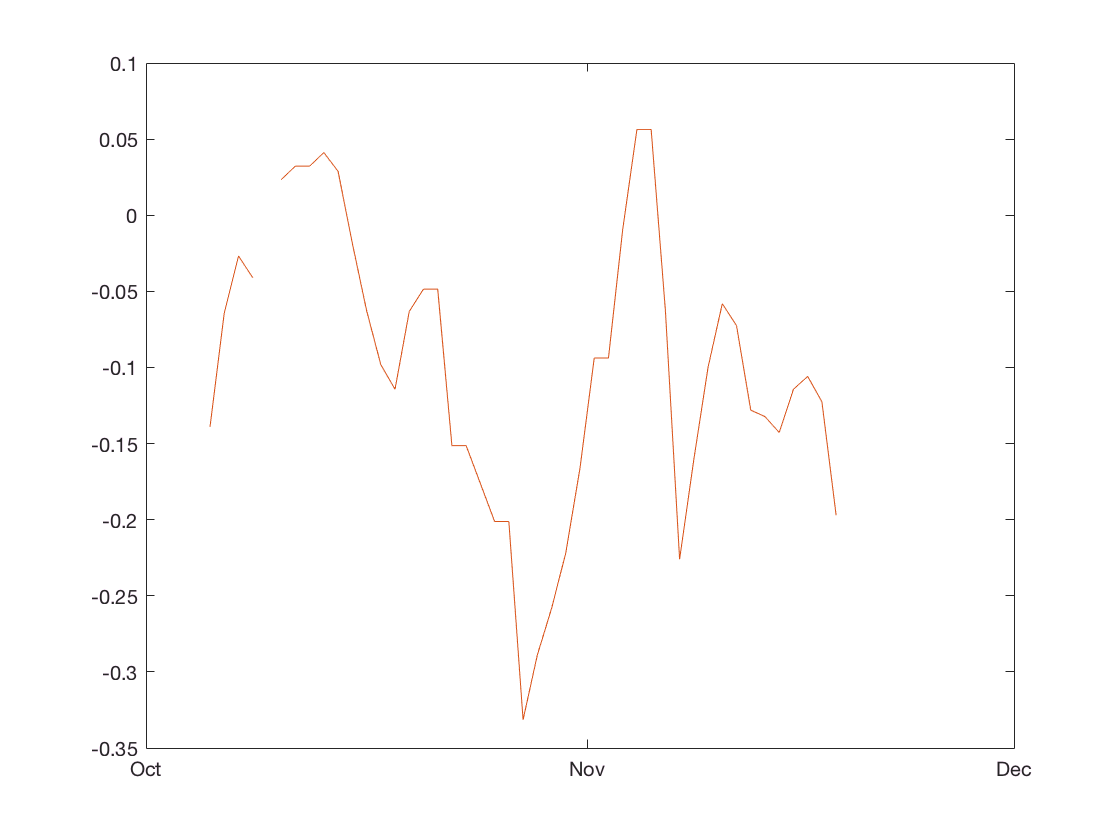


% wind stress comparison
xpos = [237 237];
ypos = [36 36];
tpos{1} = '2009-10-05';
tpos{2} = '2009-11-19';
ascat_info = erddapInfo('erdQAstress3day');
ascat = xtracto_3D(ascat_info, 'tauy', xpos, ypos, tpos);
quikscat_info = erddapInfo('erdQAstress3day');
quikscat = xtracto_3D(quikscat_info, 'tauy', xpos, ypos, tpos);
times = datenum(ascat.time);
plot(times, double(ascat.tauy), times, double(quikscat.tauy));
datetick('x', 'mmm');


% last times
xpos = [235 240];
ypos = [36 39];
tpos{1} = 'last-5';
tpos{2} = 'last';
poes_info = erddapInfo('erdAGsstamday');
poes = xtracto_3D(poes_info, 'sst', xpos, ypos, tpos);



# xtractogon examples

Sanctuay Chlorophyll

%chla in sanctuary
load('mbnms.mat');
tpos{1} = '2014-09-01';
tpos{2} = '2014-10-01';
xpoly = mbnms(:, 1);
ypoly = mbnms(:, 2);
sanctchl_info = erddapInfo('erdMH1chlamday');
sanctchl = xtractogon(sanctchl_info, 'chlorophyll', xpoly, ypoly, tpos);
myfun = @(x)log(x);
makeMap(sanctchl, sanctchl.time(1, :), myfun);

Sanctuary Bathymetry

% sanctuary bathymetry
bathy_info = erddapInfo('etopo180');
bathy = xtractogon(bathy_info, 'altitude', xpoly, ypoly);
makeMap(bathy, NaN);